# 传感器数据处理

## 第一层

clc,clear
data1= [
 1.25233,   26.5
    1.25233,   26.5
    1.25238,   26.5
    1.25236,   26.5
    1.25238,   26.5
    1.25237,   26.5
    1.25236,   26.5
    1.25234,   26.5
    1.25239,   26.5
    1.25236,   26.5
    1.25232,   26.5
    1.25236,   26.4
    1.25238,   26.4
    1.25241,   26.4
    1.25238,   26.4
    1.25233,   26.4
];
% 使用矩阵索引来提取电压和温度
voltages1 = mean(data1(:, 1));
temperatures1 = mean(data1(:, 2));
std_voltages1=std(data1(:, 1));
std_temperatures1=std(data1(:, 2));
T = table(data1(:,1), data1(:,2), 'VariableNames', {'Voltage', 'Temperature'});
% 显示表格
writetable(T, 'output.xlsx', 'Sheet', 'Floor1');

## 第二层

data2=[
    1.25174,   28.5
    1.25178,   28.4
    1.25182,   28.4
    1.25179,   28.4
    1.25179,   28.3
    1.25184,   28.3
    1.25187,   28.3
    1.25184,   28.3
    1.25182,   28.3
    1.25181,   28.3
    1.25180,   28.3
    1.25178,   28.3
    1.25175,   28.3
    1.25178,   28.3
    1.25180,   28.3
    1.25181,   28.3
];
% 使用矩阵索引来提取电压和温度
voltages2 = mean(data2(:, 1));
temperatures2 = mean(data2(:, 2));
std_voltages2=std(data2(:, 1));
std_temperatures2=std(data2(:, 2));
T = table(data2(:,1), data2(:,2), 'VariableNames', {'Voltage', 'Temperature'});
% 显示表格
writetable(T, 'output.xlsx', 'Sheet', 'Floor2');

## 第三层

data3=[
    1.25142,   28.9
    1.25146,   28.9
    1.25137,   28.9
    1.25129,   28.9
    1.25135,   28.9
    1.25133,   28.9
    1.25135,   28.9
    1.25132,   28.9
    1.25132,   28.9
    1.25133,   28.9
    1.25135,   28.9
    1.25134,   28.9
    1.25131,   28.9
    1.25132,   28.9
    1.25127,   28.9
    1.25131,   28.9
    ];
% 使用矩阵索引来提取电压和温度
voltages3 = mean(data3(:, 1));
temperatures3 = mean(data3(:, 2));
std_voltages3=std(data3(:, 1));
std_temperatures3=std(data3(:, 2));
T = table(data3(:,1), data3(:,2), 'VariableNames', {'Voltage', 'Temperature'});
% 显示表格
writetable(T, 'output.xlsx', 'Sheet', 'Floor3');

## 第四层

data4=[
 1.25082,   29.4
    1.25087,   29.4
    1.25088,   29.4
    1.25086,   29.4
    1.25083,   29.3
    1.25085,   29.4
    1.25087,   29.4
    1.25086,   29.4
    1.25083,   29.4
    1.25084,   29.4
    1.25088,   29.4
    1.25093,   29.4
    1.25087,   29.4
    1.25084,   29.4
    1.25086,   29.4
    1.25081,   29.4
    ];
voltages4 = mean(data4(:, 1));
temperatures4 = mean(data4(:, 2));
std_voltages4=std(data4(:, 1));
std_temperatures4=std(data4(:, 2));
T = table(data4(:,1), data4(:,2), 'VariableNames', {'Voltage', 'Temperature'});
% 显示表格
writetable(T, 'output.xlsx', 'Sheet', 'Floor4');

## 第五层

data5=[
 1.25009,   28.9
    1.25015,   28.9
    1.25014,   28.9
    1.25011,   28.9
    1.25012,   28.9
    1.25011,   28.9
    1.25015,   29.0
    1.25014,   29.0
    1.25014,   29.0
    1.25012,   29.0
    1.25014,   29.0
    1.25011,   29.0
    1.25013,   29.0
    1.25014,   29.0
    1.25011,   29.0
    1.25012,   29.0
   
];
voltages5 = mean(data5(:, 1));
temperatures5 = mean(data5(:, 2));
std_voltages5=std(data5(:, 1));
std_temperatures5=std(data5(:, 2));
T = table(data5(:,1), data5(:,2), 'VariableNames', {'Voltage', 'Temperature'});
% 显示表格
writetable(T, 'output.xlsx', 'Sheet', 'Floor5');

## 电压误差图

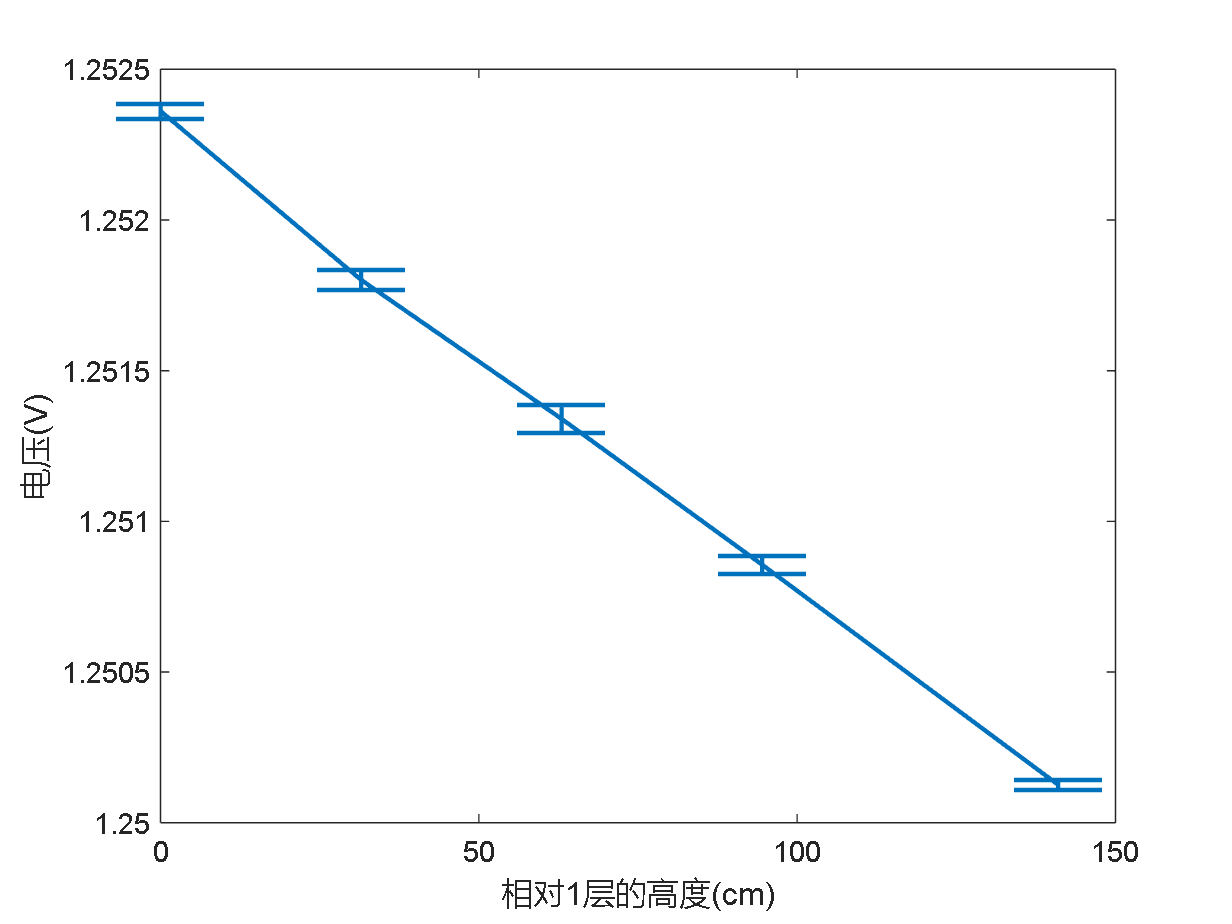

error_voltage =[std_voltages1;std_voltages2;std_voltages3;std_voltages4;std_voltages5];

voltage = [voltages1;voltages2;voltages3;voltages4;voltages5];
% 电压
x=[0,10.5*30,10.5*60,10.5*90,10.5*90+30*15.5]./10;
errorbar(x,voltage,error_voltage,'CapSize',30,'LineWidth',1.5,"MarkerSize",10,...
    "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90]);
ylabel('电压(V)');
xlabel('相对1层的高度(cm)');

## 温度误差图

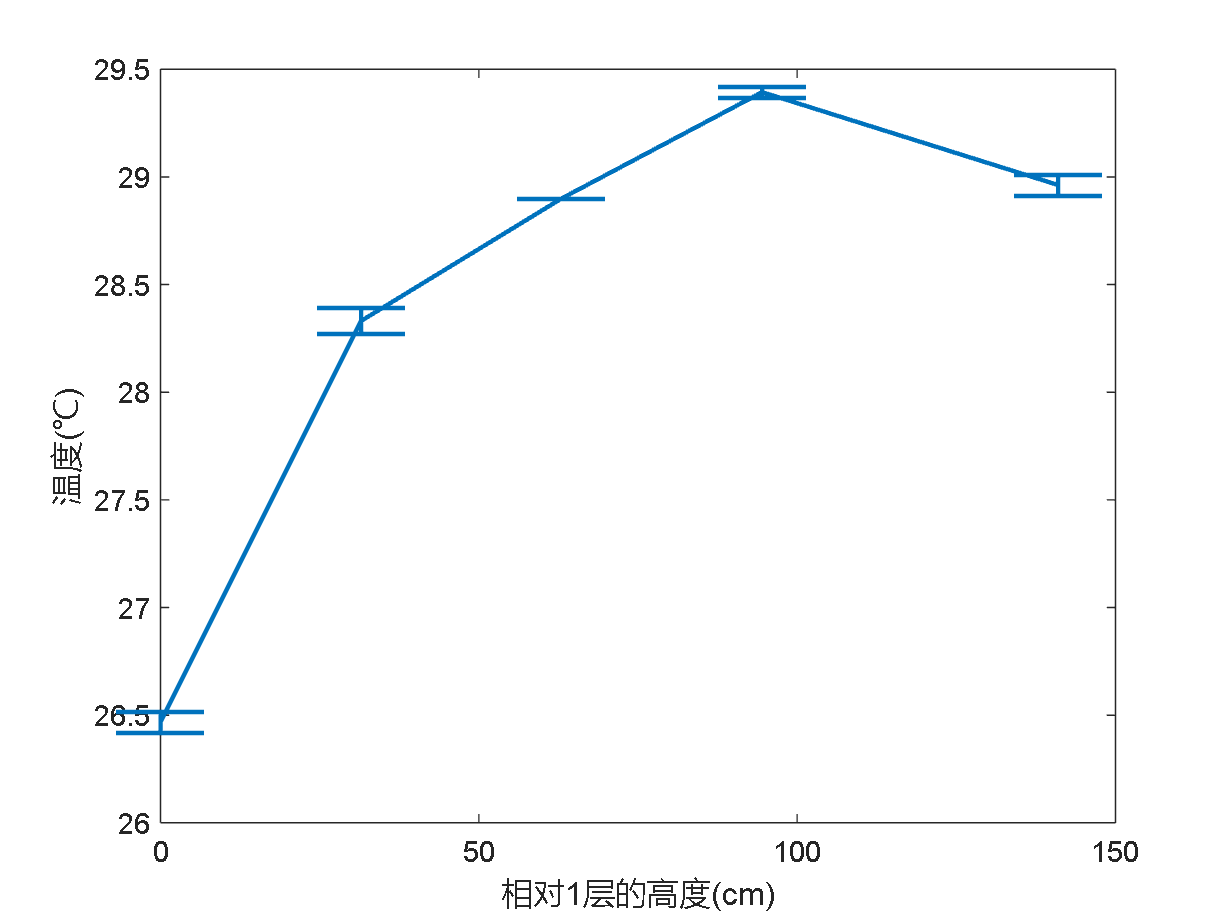

error_temperature = [std_temperatures1;std_temperatures2;std_temperatures3;std_temperatures4;std_temperatures5];

temperature = [temperatures1;temperatures2;temperatures3;temperatures4;temperatures5];
% 电压

errorbar(x,temperature,error_temperature,'CapSize',30,'LineWidth',1.5,"MarkerSize",10,...
    "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90]);
ylabel('温度(℃)');
xlabel('相对1层的高度(cm)');

## 楼层高度转换

H=zeros(1,5);
H(1)=height(voltages1,temperatures1);

p = 100.8783

该楼层的气压为 1.008783e+02 KPa

H(2)=height(voltages2,temperatures2);

p = 100.8332

该楼层的气压为 1.008332e+02 KPa

H(3)=height(voltages3,temperatures3);

p = 100.7960

该楼层的气压为 1.007960e+02 KPa

H(4)=height(voltages4,temperatures4);

p = 100.7570

该楼层的气压为 1.007570e+02 KPa

H(5)=height(voltages5,temperatures5)

p = 100.6982

该楼层的气压为 1.006982e+02 KPa

H =    38.7527   42.9404   46.2798   49.7796   54.8710


test=height(1.25349,25.7)

p = 100.9692

该楼层的气压为 1.009692e+02 KPa

test = 30.7726

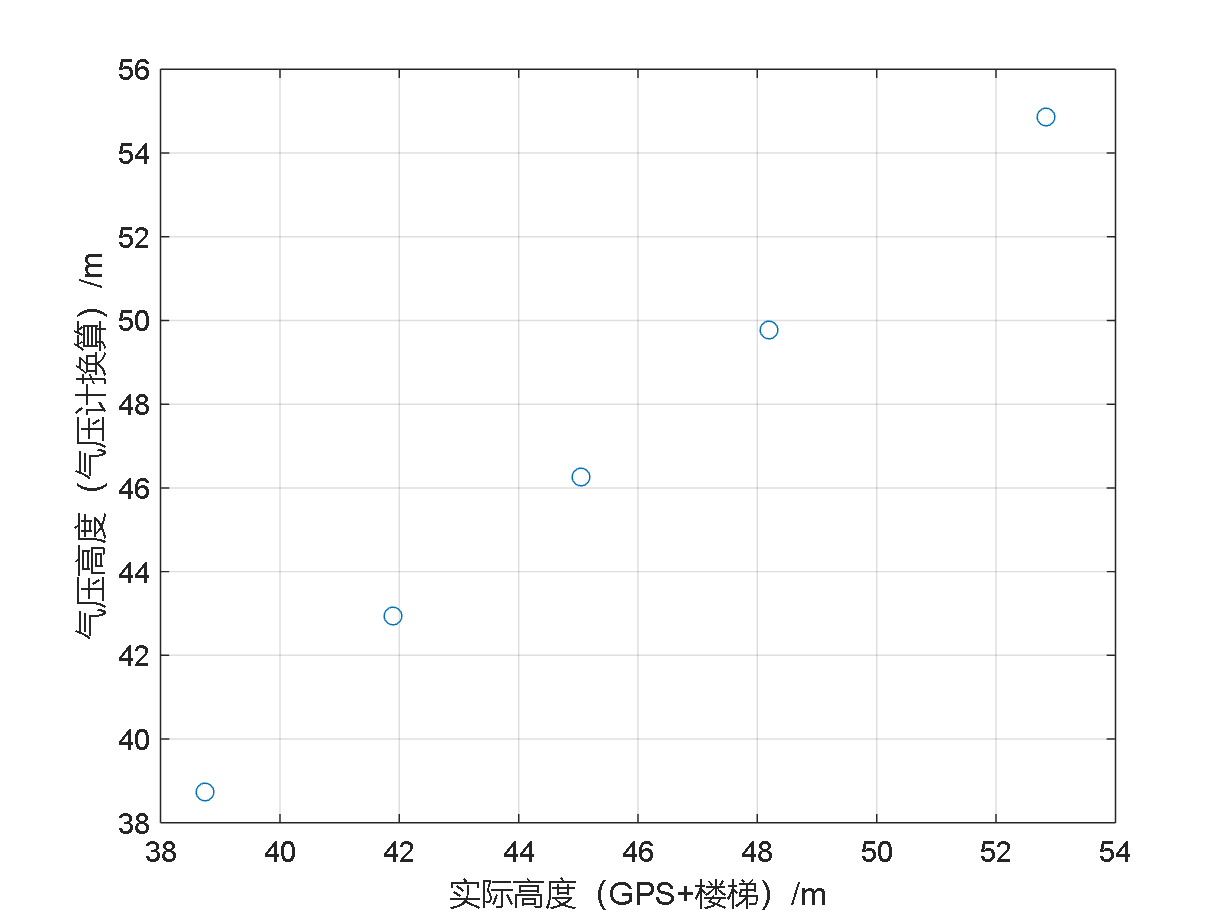

step=(x+387.5)./10;
plot(step,H,'o')
xlabel('实际高度（GPS+楼梯）/m');
ylabel('气压高度（气压计换算）/m');
grid on
hold on

## 最佳拟合

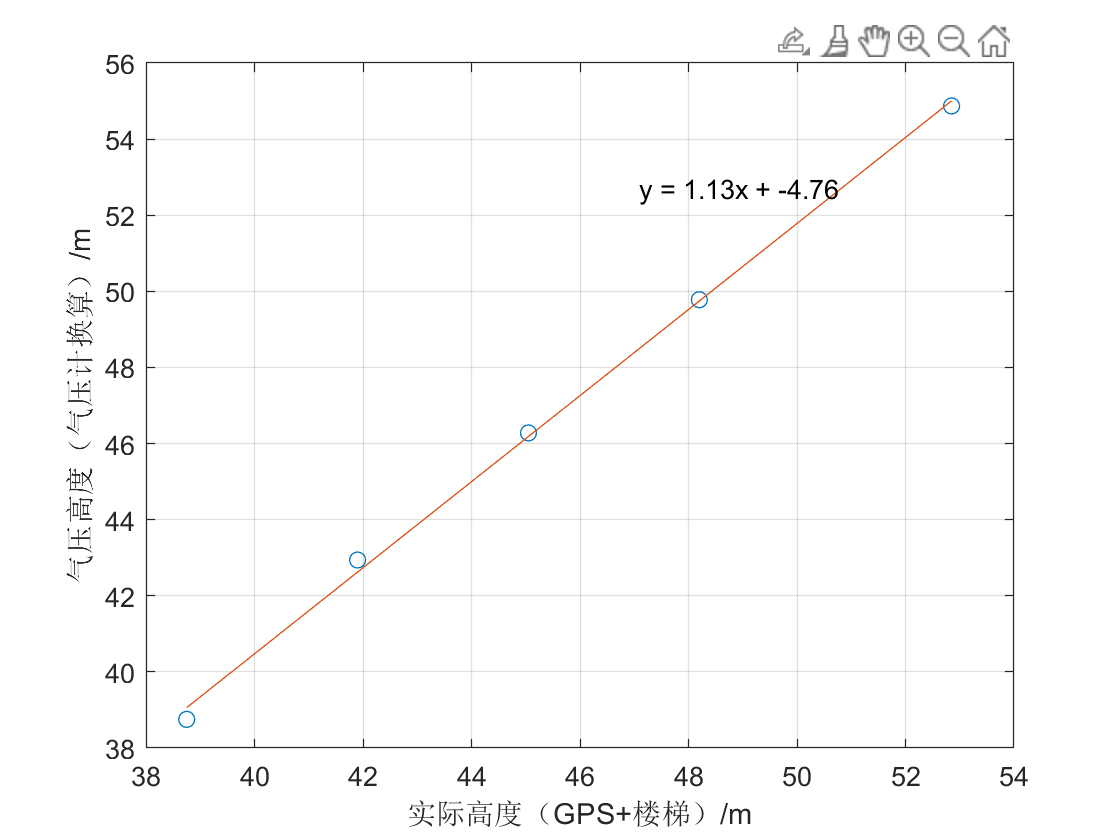

[p,s]=polyfit(step,H,1);
hfit=polyval(p,step);
plot(step,hfit,'-');
R=corrcoef(H,hfit);
R_squared = R(1, 2)^2;
line_eq = sprintf('y = %.2fx + %.2f', p(1), p(2));
gtext(line_eq);
hold on

## k=1最佳拟合

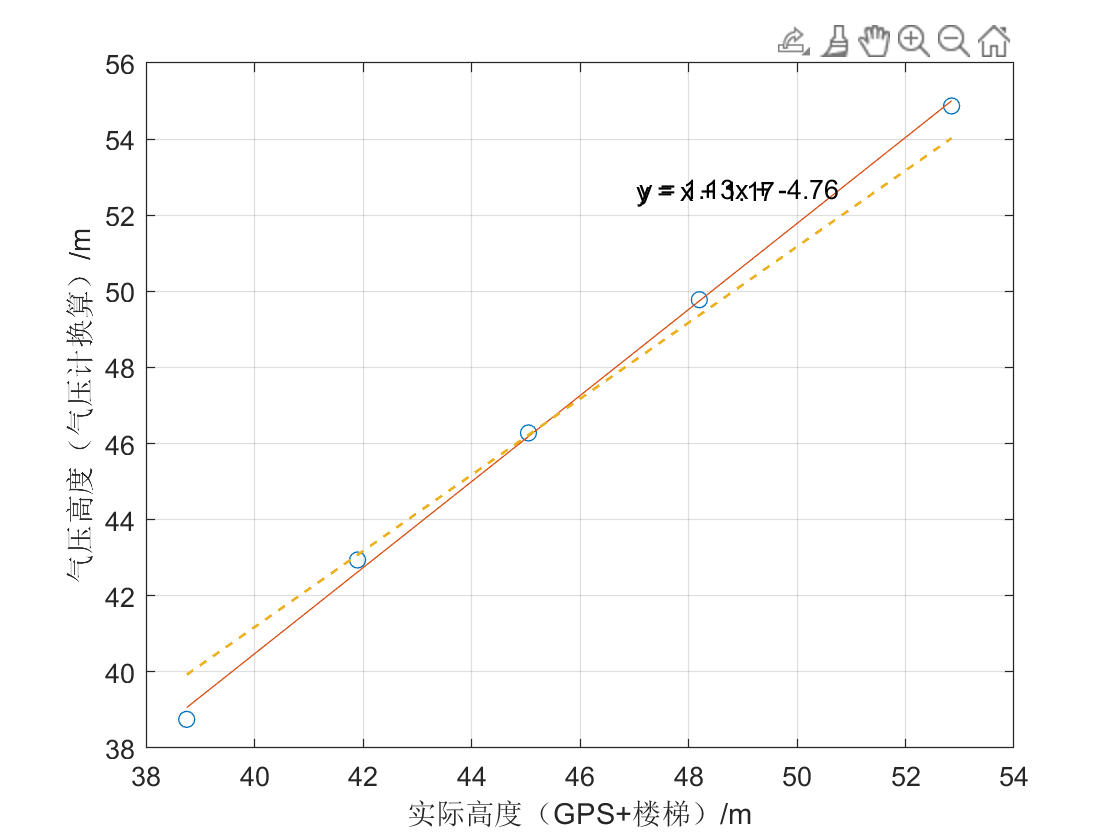

b = mean(H - step);
yfit = step + b;
R1 = corrcoef(H, yfit);
R1_squared = R1(1, 2)^2;
plot(step,yfit,'LineWidth',1,'LineStyle','--');
line_eq1 = sprintf('y = x + %.2f', b);
gtext(line_eq1);
hold on

## b=0 最佳拟合

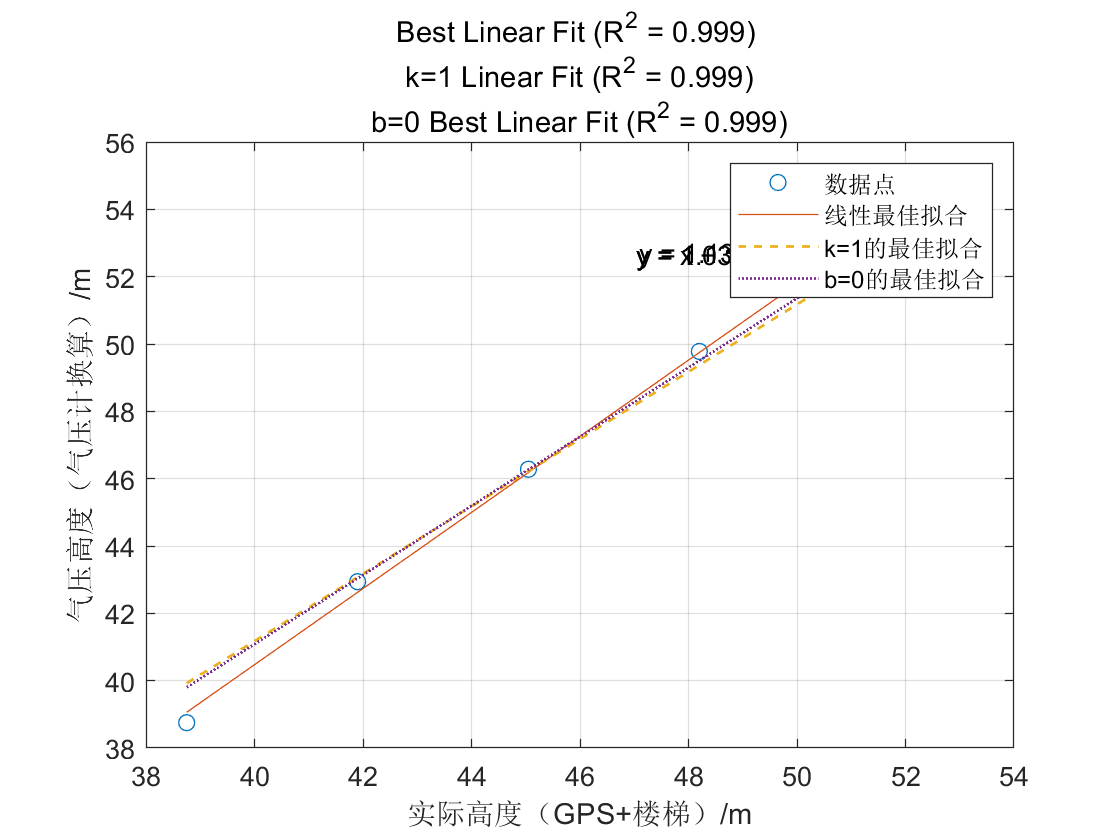

%使用最小二乘法来计算k
m=(step * H') / (step * step');
y2fit = m * step;
R2 = corrcoef(H, y2fit);
R2_squared = R2(1, 2)^2;
plot(step,y2fit,'LineWidth',1,'LineStyle',':');
line_eq2 = sprintf('y = %.2fx', m);
gtext(line_eq2);
legend('数据点','线性最佳拟合','k=1的最佳拟合','b=0的最佳拟合')
title(sprintf(['Best Linear Fit (R^2 = %.3f) \n ' ...
    'k=1 Linear Fit (R^2 = %.3f) \n' ...
    'b=0 Best Linear Fit (R^2 = %.3f)'], R_squared,R1_squared,R2_squared));

function h=height(vol,temp)%输出单位是m
p=vol/(0.2*10^-3*62.0729)
fprintf("该楼层的气压为 %d KPa",p);
T=temp+273.15;
P_0=101.325;
R=287.05;
M=0.0289644;
g=9.80665;
h = -(R * T * log(p / P_0)) / (g);
%h=T/(-0.0065)*(1-(p/101.325)^(29.27*-0.0065));
%h=T/(-0.0065)*(1-(vol/(760*0.13332*0.2*61*10^-3))^(29.27*-0.0065));
end